# Tarea 2. Seguimiento de trayectoria de un sistema lineal de múltiples entradas

Marco Antonio Esquivel Basaldua

Se considera el siguiente sistema lineal de la forma


$$\dot{x} =\textrm{Ax}+\;\textrm{Bu}$$



$$y=Cx$$


donde

$A=\left\lbrack \begin{array}{cccc}
1 & -1 & 0 & 0\\
0 & 2 & 0 & 0\\
0 & 0 & 2 & 1\\
0 & 0 & 0 & -1
\end{array}\right\rbrack$,  $B=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & 0\\
-1 & 1\\
1 & 2
\end{array}\right\rbrack$, $C=\left\lbrack \begin{array}{cccc}
1 & 1 & -1 & 0\\
-2 & 1 & 0 & 1
\end{array}\right\rbrack$

clear, clc
A = [1 -1 0 0;0 2 0 0;0 0 2 1;0 0 0 -1];
B = [0 1;-1 0;-1 1;1 2];
C = [1 1 -1 0;-2 1 0 1];

Donde las dimensiones de la matriz $A$ son $n\times n=4\times 4$, y las dimensiones de $B$ son $n\times p=4\times 2$

[n, p] = size(B)

n = 4

p = 2

Como primer condición para saber si es posible realizar el seguimiento de trayectorias para un sistema MIMO es que el sistema sea controlable. Para ello el rango de la matriz de controlabilidad debe ser igual al orden del sistema $rank(\mathcal{C}) =n $.


$$\mathcal{C} = [B, AB,A^2B,\cdots, A^{n-1}B]$$


C_ = zeros(n,n*p);
for i = 1:n
    index = i*p;
    C_(:,index-1:index) = A^(i-1)*B;
end
C_

C_ =      0     1     1     1     3     1     7     1
    -1     0    -2     0    -4     0    -8     0
    -1     1    -1     4    -3     6    -5    14
     1     2    -1    -2     1     2    -1    -2


rank(C_)

ans = 4

Otra forma de determinar si un sistema es controlable es encontrando los índices de controlabilidad. Si la suma de los índices es $\mu_1 +\mu_2 +\cdots +\mu_p =n$ entonces el sistema es controlable.

mu = ctr_indeces(A,B)

mu =      2
     2


sum(mu)

ans = 4

## 1) Transformación del sistema de error a la forma canónica controlable

El sistema de error se conoce como el sistema que se forma de restar a cada una de las salidas del sistema el valor de referencia deseado por salida. Adicionalmente se obtiene el grado relativo del sistema como la cantidad de veces que es necesario derivar los errores para que aparezca la enrtada de control. Cabe señalar que una condición más para que se pueda aplicar el control de seguimiento para este sistema es que el grado relativo sea igual al orden del sistema, en este caso $n=4$. Al tratarse de un sistema de dos entradas, se obtendrán dos índices de grado relativo, la suma de ambos debe ser igual a $n$ para decir que el problema se seguimiento puede ser aplicado.


$$\mathit{\mathbf{e}}=\left\lbrack \begin{array}{c}
e_{11} \\
e_{12} \\
e_{21} \\
e_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
e_{11} \\
{\dot{e} }_{11} \\
e_{21} \\
{\dot{e} }_{21} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 +x_2 -x_3 -y_1^r \\
x_1 +x_2 -2x_3 -x_4 -{\dot{y} }_1^r \\
-2x_1 +x_2 +x_4 -y_2^r \\
-2x_1 +4x_2 -x_4 -{\dot{y} }_2^r 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 1 & -1 & 0\\
1 & 1 & -2 & -1\\
-2 & 1 & 0 & 1\\
-2 & 4 & 0 & -1
\end{array}\right\rbrack x-\left\lbrack \begin{array}{c}
y_1^r \\
{\dot{y} }_1^r \\
y_2^r \\
{\dot{y} }_2^r 
\end{array}\right\rbrack$$


Para cada error asociado a cada salida se tuvo que derivar dos veces, por tanto los grados relativos son 2 y 2, y suma resulta en 4 siendo este el orden del sistema. El desarrollo de estos errores es como sigue.


$$e_{11} =x_1 +x_2 -x_3 -y_1^r$$



$${\dot{e} }_{11} =e_{12} =x_1 +x_2 -2x_3 -x_4 -{\dot{y} }_1^r$$



$${\dot{e} }_{12} =x_1 +x_2 -4x_3 -x_4 -3u_2 -{\ddot{y} }_1^r$$



$$e_{21} =-2x_1 +x_2 +x_4 -y_2^r$$



$${\dot{e} }_{21} =e_{22} =-2x_1 +4x_2 -x_4 -{\dot{y} }_2^r$$



$${\dot{e} }_{22} =-2x_1 +10x_2 +x_4 -5u_1 -4u_2 -{\ddot{y} }_2^r$$


A partir de este cambio de variables se define la matriz de transformación $T$ como


$$T=\left\lbrack \begin{array}{cccc}
1 & 1 & -1 & 0\\
1 & 1 & -2 & -1\\
-2 & 1 & 0 & 1\\
-2 & 4 & 0 & -1
\end{array}\right\rbrack$$


T = [1 1 -1 0;1 1 -2 -1;-2 1 0 1;-2 4 0 -1]

T =      1     1    -1     0
     1     1    -2    -1
    -2     1     0     1
    -2     4     0    -1


donde $e=\textrm{Tx}$

## 2) El sistema de error

Definiendo $\dot{x} =\textrm{Ax}+\textrm{Bu}$, $e=Tx-y$, entonces


$$\dot{e} =T\dot{x} -\dot{y} =T\left(Ax+Bu\right)-\dot{y} =TAx+TBu-\dot{y} ={TAT}^{-1} \left(e+y\right)+TBu-\dot{y}$$


Definimos

$A_e ={TAT}^{-1}$ y $B_e =TB$


$$\dot{e} =A_e e+A_e y+B_e u-\dot{y}$$


A partir de esta expresión se define el valor del vector de controles como


$$u=B^{-1} \left(\dot{e} +\dot{y} -A_e e+A_e y\right)$$


Como última condición para saber si es posible aplicar el control de trayectoria a este sistema se debe obtener el rango de la matriz $B_e$, este resultado debe ser igual al numero de salidas.

Ae = T*A/T

Ae =          0    1.0000         0         0
   -0.4000    2.2000    0.8000   -0.4000
         0         0         0    1.0000
    4.8000   -2.4000    0.4000    1.8000


Be = T*B

Be =      0     0
     0    -3
     0     0
    -5    -4


rank(Be)

ans = 2

Cabe señalar que esto es equivalente a encontrar el rango de la matriz reducida de $B_e$, $B_{\textrm{er}}$, que consiste en eliminar las filas de $B_e$ que solo contienen ceros.

Ber = [Be(2,:); Be(4,:)]

Ber =      0    -3
    -5    -4


rank(Ber)

ans = 2

Una vez calculadas las matrices $A_e$ y $B_e$ el sistema de error resulta como


$$\dot{e} =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-0\ldotp 4 & 2\ldotp 2 & 0\ldotp 8 & -0\ldotp 4\\
0 & 0 & 0 & 1\\
4\ldotp 8 & -2\ldotp 4 & 0\ldotp 4 & 1\ldotp 8
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
e_{11} \\
e_{12} \\
e_{21} \\
e_{22} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & -3\\
0 & 0\\
-5 & -4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


## 3) Controlador de seguimiento de trayectorias

Se desea diseñar un controlador para que el sistema siga una trayectoria de tal forma que la salida $y_1$ siga una referencia constante $y_1^r =1$ y la salida $y_2$ una referencia senidal $y_2^r =\sin \left(2t\right)$. A partir del estado inicial $x_i ={\left\lbrack \begin{array}{cccc}
1 & 0 & -1 & 0
\end{array}\right\rbrack }^T$ y asignando los polos al sistema $p=\left\lbrace -1,-2,-2,-3\right\rbrace$.

A partir de la expresión para $\dot{e}$ en la sección anterios se define el controlador como $u=-\textrm{Ke}$ y se desglosa cada entrada del vector $\dot{e}$ como


$${\dot{e} }_{11} =e_{12}$$



$${\dot{e} }_{12} =-0\ldotp 4e_1 +2\ldotp 2e_2 +0\ldotp 8e_3 -0\ldotp 4e_4 -3u_2$$



$${\dot{e} }_{21} =e_{22}$$



$${\dot{e} }_{22} =4\ldotp 8e_1 -2\ldotp 4e_2 +0\ldotp 4e_3 +1\ldotp 8e_4 -5u_1 -4u_2$$


Se desea llevar el sistema a la forma


$${\dot{e} }_{11} =e_{12}$$



$${\dot{e} }_{12} =v_1 =-k_1 e_{11} -k_2 e_{12}$$



$${\dot{e} }_{21} =e_{22}$$



$${\dot{e} }_{22} =v_2 =-k_3 e_{21} -k_4 e_{22}$$


### a) Asignación de dinámicas independientes por bloques

Una forma de lograr el control es mediante la asignación de controles por separado para eliminar la dinámica de cada uno de los bloques formado en la matriz $A_e$. Como se ha visto antes, se concluyó que el sistema es desacoplable y dado que los índices de controlabilidad fueron 2 y 2, los bloques a tomar en cuenta son las filas 2 y 4 para las matrices $A_e$ y $B_e$.

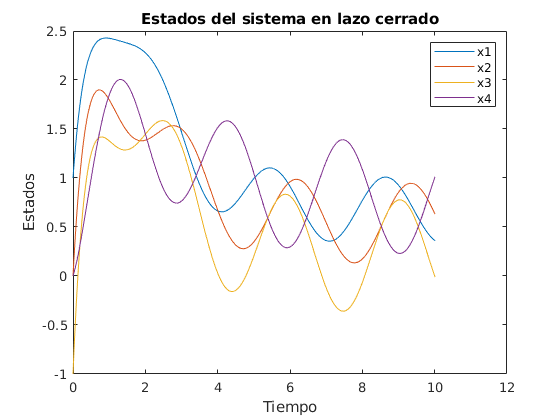

xi = [1 0 -1 0]';
x = xi;
yi = C*xi;
y = yi;
dt = 0.01;

time = []; all_e = zeros(n,1); all_u = zeros(p,1);

for t = 0:dt:10.0
    yr1     = 1;
    dyr1    = 0;
    ddyr1   = 0;
    yr2     = sin(2*t);
    dyr2    = 2*cos(2*t);
    ddyr2   = -4*sin(2*t);
    
    rv = [yr1; dyr1; yr2; dyr2];
    e = T*xi - rv;
    rvT = T*A/T*rv;
    
    % Eliminar la dinamica de cada uno, que son los terminos Ae*e
    v1_aux = -[1 2]*e(1:2); %Polos para los 2 primeros errores
    v2_aux = -[2 3]*e(3:4); %Polos para los 2 segundos errores
    u = Ber\[-Ae(2,:)*e + v1_aux - rvT(2) + ddyr1; -Ae(4,:)*e + v2_aux - rvT(4) + ddyr2];
    
    
    yi = C*xi;   
    xi = xi + dt*(A*xi + B*u);
    
    time = [time t];
    x = [x xi];
    y = [y yi];
    
    all_e = [all_e, e]; all_u = [all_u u];
end

time = [time time(1,end)+dt];

figure
plot(time,x(1,:), time,x(2,:), time,x(3,:), time,x(4,:))
title('Estados del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Estados')
legend('x1','x2','x3','x4')

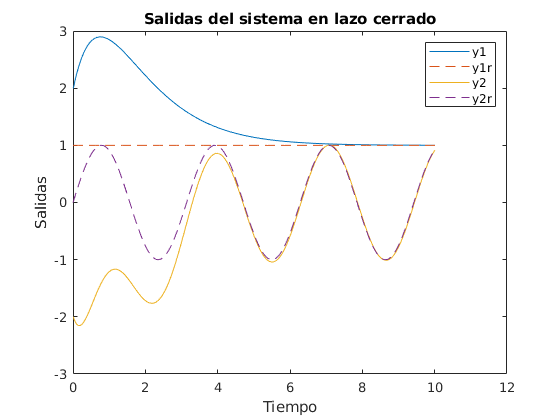

figure
plot(time,y(1,:), time,ones(1,length(time)), '--', time,y(2,:), time, sin(2*time), '--')
title('Salidas del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Salidas')
legend('y1','y1r','y2','y2r')

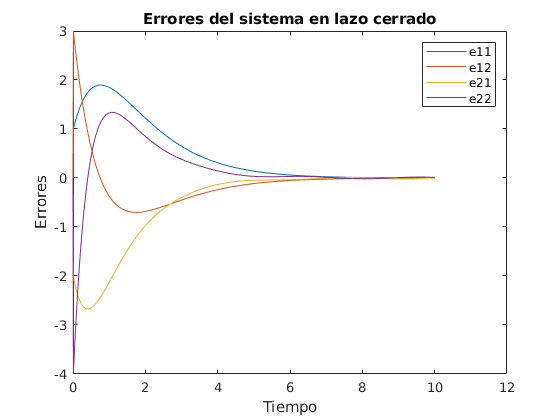

figure
plot(time,all_e(1,:), time,all_e(2,:), time,all_e(3,:), time,all_e(4,:))
title('Errores del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Errores')
legend('e11','e12','e21','e22')

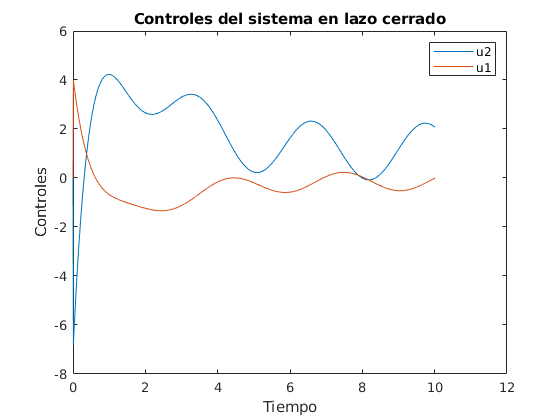

figure
plot(time,all_u(1,:), time,all_u(2,:))
title('Controles del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Controles')
legend('u2','u1')

### b) Asignación de dinámica completa

Otra forma de realizar el seguimiento de trayectorias es mediante la asignación de toda la dinámica del sistema mediante la reubicación de todos los polos. Se genera este método con el mismo sistema, mismas condiciones iniciales y mismas referencias de seguimiento que en el ejemplo pasado asignando a los mismos polos deseados.

Ke = place(Ae,Be,[-1 -2 -2 -3])

Ke =    -0.1839    2.0414   -0.0259   -0.9463
   -1.4373   -2.1853   -0.8897   -0.1782


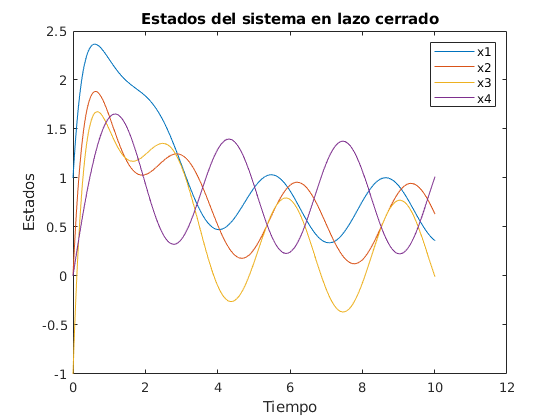

xi = [1 0 -1 0]';
x = xi;
yi = C*xi;
y = yi;
dt = 0.01;

time = []; all_e = zeros(n,1); all_u = zeros(p,1);

for t = 0:dt:10.0
    yr1     = 1;
    dyr1    = 0;
    ddyr1   = 0;
    yr2     = sin(2*t);
    dyr2    = 2*cos(2*t);
    ddyr2   = -4*sin(2*t);
    
    rv = [yr1; dyr1; yr2; dyr2];
    e = T*xi-rv;
    rvT = T*A/T*rv;
    
    % Eliminar la dinamica de cada uno, que son los terminos Ae*e
    u = -Ke*e + Ber\([-rvT(2) + ddyr1; -rvT(4) + ddyr2]);
    
    yi = C*xi;   
    xi = xi + dt*(A*xi + B*u);
    
    time = [time t];
    x = [x xi];
    y = [y yi];
    
    all_e = [all_e, e]; all_u = [all_u u];
end

time = [time time(1,end)+dt];

figure
plot(time,x(1,:), time,x(2,:), time,x(3,:), time,x(4,:))
title('Estados del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Estados')
legend('x1','x2','x3','x4')

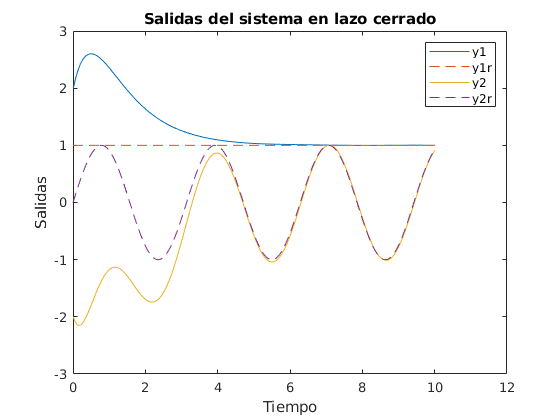

figure
plot(time,y(1,:), time,ones(1,length(time)), '--', time,y(2,:), time, sin(2*time), '--')
title('Salidas del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Salidas')
legend('y1','y1r','y2','y2r')

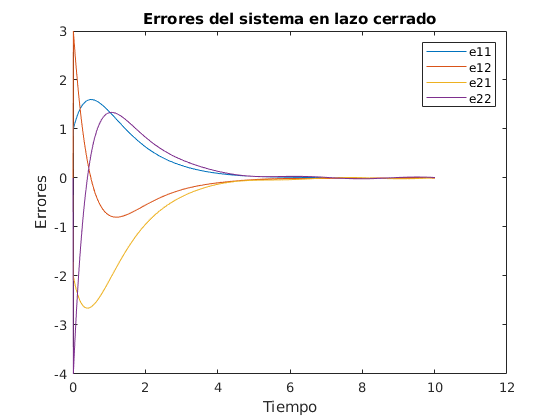

figure
plot(time,all_e(1,:), time,all_e(2,:), time,all_e(3,:), time,all_e(4,:))
title('Errores del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Errores')
legend('e11','e12','e21','e22')

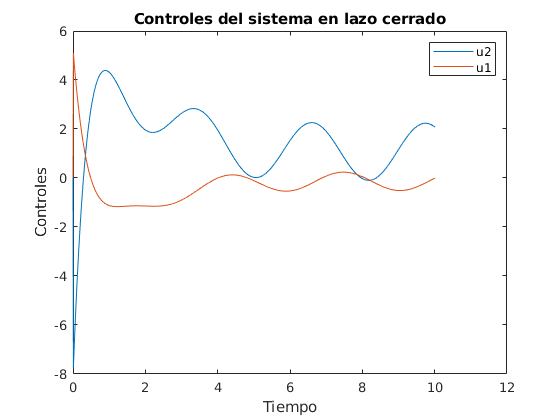

figure
plot(time,all_u(1,:), time,all_u(2,:))
title('Controles del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Controles')
legend('u2','u1')

## 4) Acelerar convergencia de una sola salida

Una forma de hacer que una sola de las salidas converja más rápido hacia su referencia, es cambiando únicamente los polos que afectan a dicha salida. Tomando el ejemplo de la sección 3a y cambiando los polos que afectan a la primer salida de $\left\lbrace -1,-2\right\rbrace$ a $\left\lbrace -15,-10\right\rbrace$ se obtienen los sigueintes resultados. 

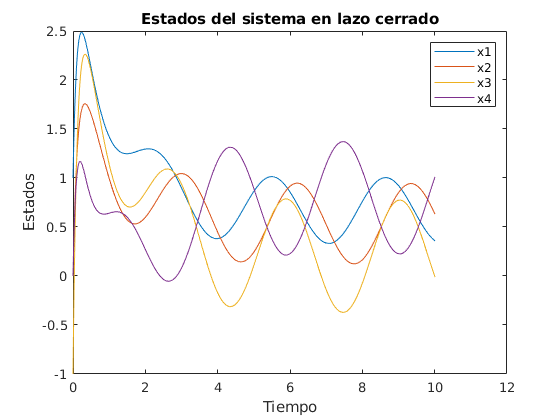

xi = [1 0 -1 0]';
x = xi;
yi = C*xi;
y = yi;
dt = 0.01;

time = []; all_e = zeros(n,1); all_u = zeros(p,1);

for t = 0:dt:10.0
    yr1     = 1;
    dyr1    = 0;
    ddyr1   = 0;
    yr2     = sin(2*t);
    dyr2    = 2*cos(2*t);
    ddyr2   = -4*sin(2*t);
    
    rv = [yr1; dyr1; yr2; dyr2];
    e = T*xi-rv;
    rvT = T*A/T*rv;
    
    % Eliminar la dinamica de cada uno, que son los terminos Ae*e
    v1_aux = -[15 10]*e(1:2); %Polos para los 2 primeros errores
    v2_aux = -[2 3]*e(3:4); %Polos para los 2 segundos errores
    u = Ber\[-Ae(2,:)*e + v1_aux - rvT(2) + ddyr1; -Ae(4,:)*e + v2_aux - rvT(4) + ddyr2];
    
    
    yi = C*xi;   
    xi = xi + dt*(A*xi + B*u);
    
    time = [time t];
    x = [x xi];
    y = [y yi];
    
    all_e = [all_e, e]; all_u = [all_u u];
end

time = [time time(1,end)+dt];

figure
plot(time,x(1,:), time,x(2,:), time,x(3,:), time,x(4,:))
title('Estados del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Estados')
legend('x1','x2','x3','x4')

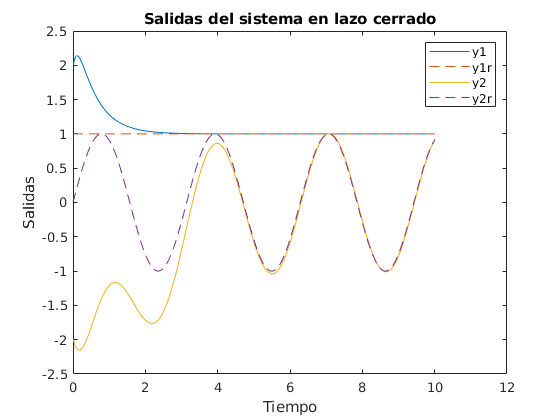

figure
plot(time,y(1,:), time,ones(1,length(time)), '--', time,y(2,:), time, sin(2*time), '--')
title('Salidas del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Salidas')
legend('y1','y1r','y2','y2r')

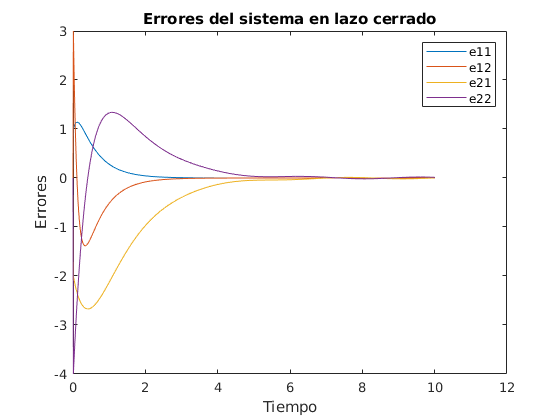

figure
plot(time,all_e(1,:), time,all_e(2,:), time,all_e(3,:), time,all_e(4,:))
title('Errores del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Errores')
legend('e11','e12','e21','e22')

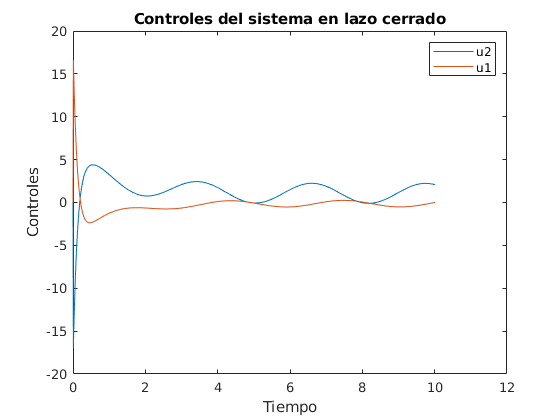

figure
plot(time,all_u(1,:), time,all_u(2,:))
title('Controles del sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Controles')
legend('u2','u1')

Se puede observar que la salida $y_1$ converge más rápidamente a su valor de referencia pasando de cerca de 5 segundos a poco más de 2 segundos sin que se afecte el comportamiento de la salida $y_2$.